## **Compasion Between Delay-Coordinate Reconstruction And Derivative Reconstruction With Noise Data  **

Attractor of the Lorenz system

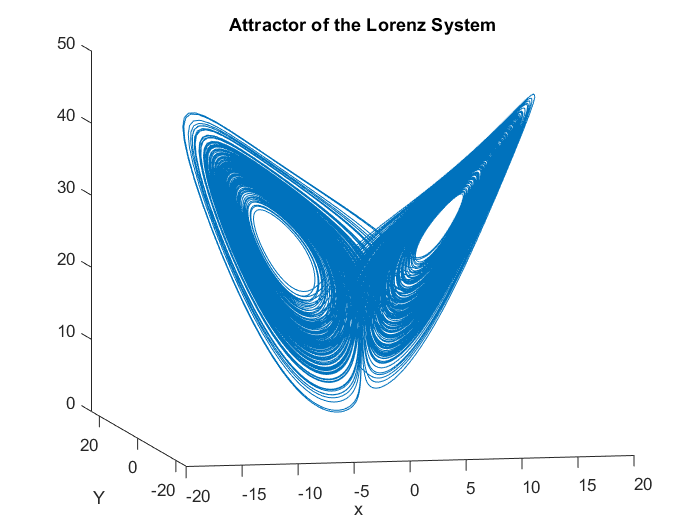

clc
clear
%Lorenz，rung（funciton，【ragne】，【initial】，accurancy）
a=0;
b=200;
c=[0 2 9];
h=0.01;
[t,y]=rung(@lorenz,[a b],c,h);

figure(1)
plot3(y(1,:), y(2,:), y(3,:))
view(-12,9)
title("Attractor of the Lorenz System")

original and noise data 

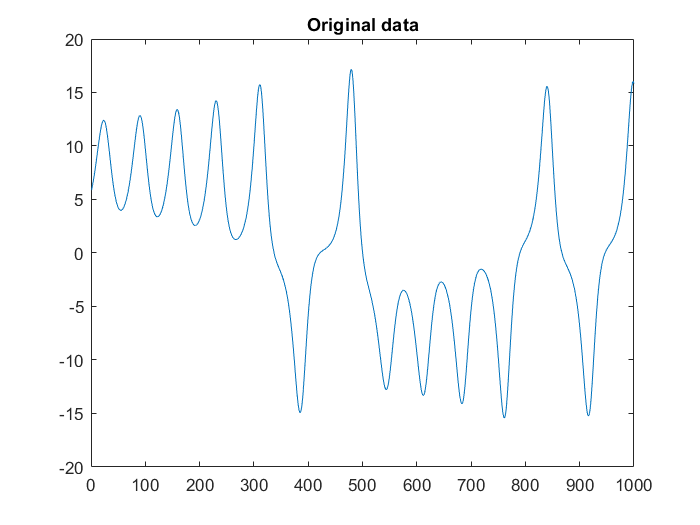

X = y(1,1e4:2e4);  % original data
plot(X(1:1e3))   
title("Original data")

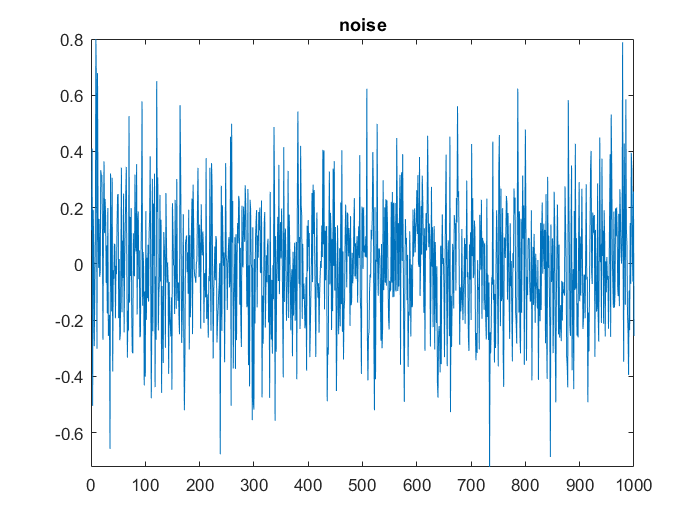


noise = wgn(1, length(X), 0.05,'linear');
plot(noise(1:1e3))
axis([0 inf -inf inf])
title("noise")

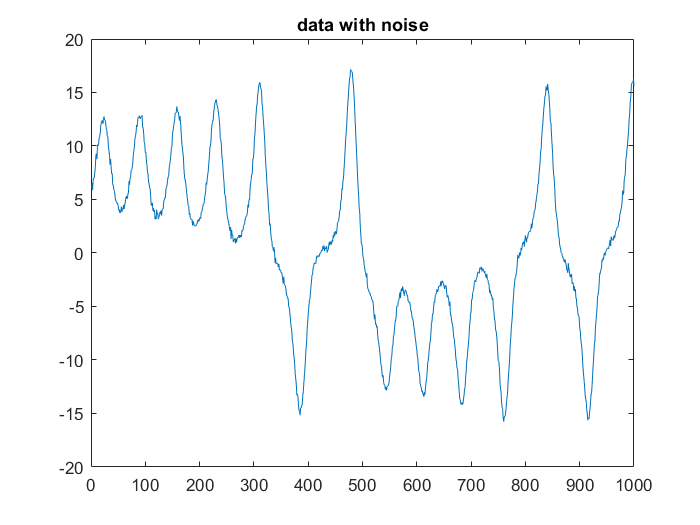


XN = X + noise;
plot(XN(1:1e3))
title('data with noise')

delay-coordinate reconstruciton

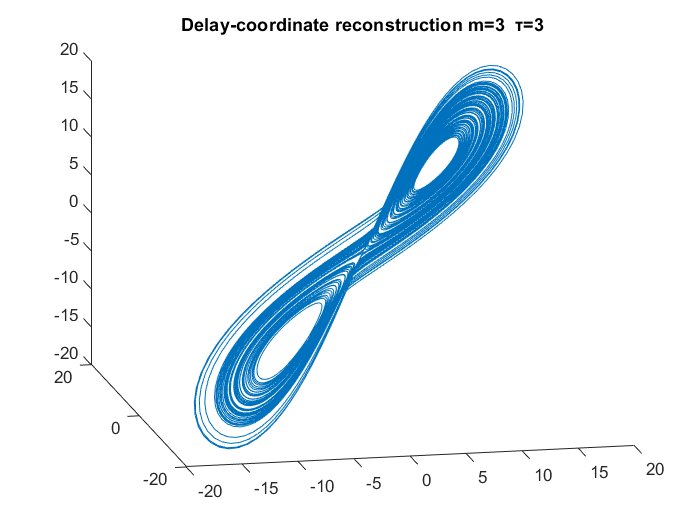

m = 3;     % embed dimesion
tao = 3;   % delay time
X_delay = reconstruction(X, m, tao);
plot3(X_delay(1,:), X_delay(2,:), X_delay(3,:))
title(['Delay-coordinate reconstruction m='  num2str(m) '  τ=' num2str(tao)])
view(-12,19)

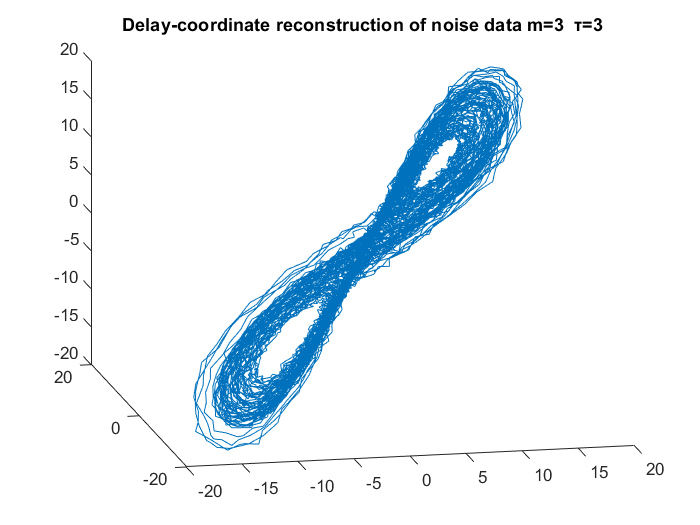


XN_delay = reconstruction(XN, m, tao);
plot3(XN_delay(1,:), XN_delay(2,:), XN_delay(3,:))
title(['Delay-coordinate reconstruction of noise data m='  num2str(m) '  τ=' num2str(tao)])
view(-12,19)

Derivative reconstruction

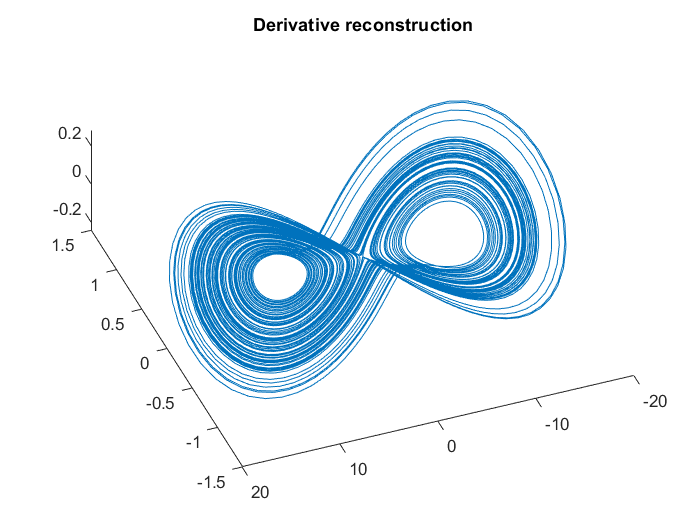

n = length(X_delay);  % length of delay

X_dif2 = diff(X);
X_dif3 = diff(X,2);
plot3(X(1:n),X_dif2(1:n),X_dif3(1:n))
view([-158.924 -68.458])
title('Derivative reconstruction')

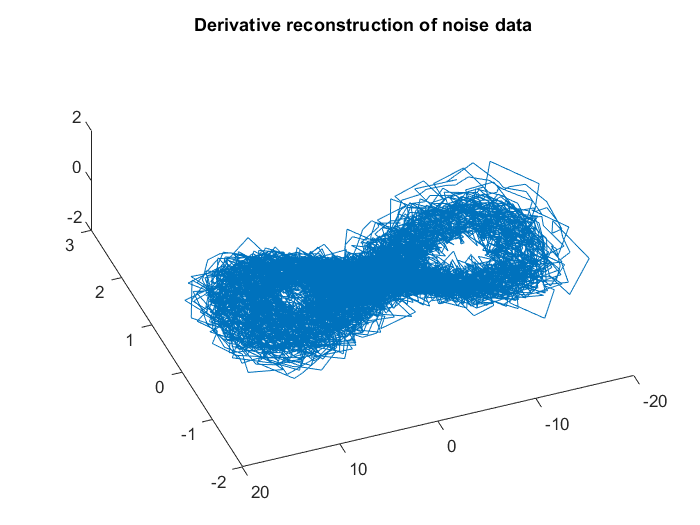

XN_dif2 = diff(XN);
XN_dif3 = diff(XN,2);
plot3(XN(1:n),XN_dif2(1:n),XN_dif3(1:n))
view([-158.924 -68.458])
title('Derivative reconstruction of noise data')